clear, clc, close all;

raw_record = importdata('data\excit\2023-07-22_19-42.csv');

addpath 'F:\Master\毕设文件\code\Dynamic_Parameter_Identification_for_Rokae_xMate\excitation\utils';
PERIOD = 0.001;

torque_record = raw_record.data(:, 2 : 8);
point_record = raw_record.data(:, 9 : 15);
speed_record = raw_record.data(:, 16 : 22);

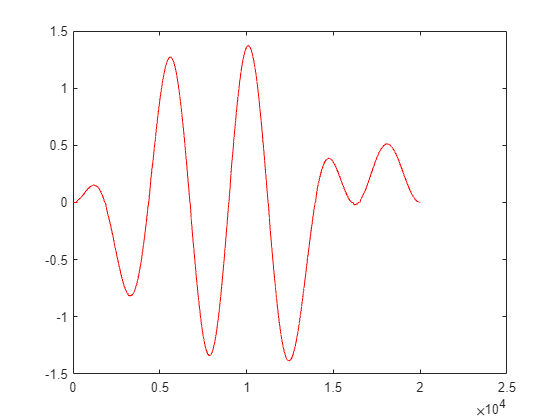

figure(1);
plot(speed_record(:, 1), 'r');

[row, column] = size(speed_record);
acceleration_record = zeros(row, column);
acceleration_record(1, :) = speed_record(1, :) / PERIOD;
for i = 2 : row
    acceleration_record(i, :) = (speed_record(i, :) - speed_record(i - 1, :)) / PERIOD;
end

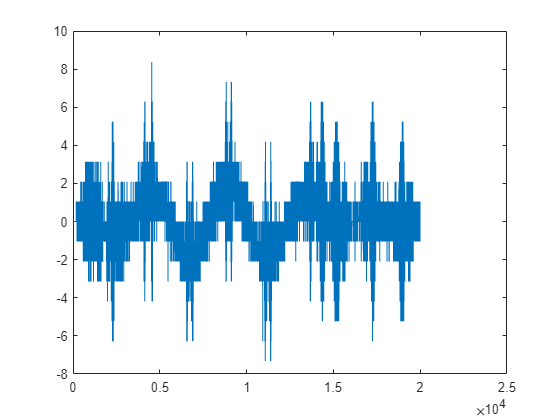

figure(2);
plot(acceleration_record(:, 1));

% save("data\excit\excit_ang_record.mat", "point_record");
% save("data\excit\excit_vel_record.mat", "speed_record");
% save("data\excit\excit_acc_record.mat", "acceleration_record");
% save("data\excit\excit_torque_record.mat", "torque_record");
% writematrix(point_record, '.\data\excit\excit_ang_record.txt', 'Delimiter', ' ');
% writematrix(speed_record, '.\data\excit\excit_vel_record.txt', 'Delimiter', ' ');
% writematrix(acceleration_record, '.\data\excit\excit_acc_record.txt', 'Delimiter', ' ');
% writematrix(torque_record, '.\data\excit\excit_torque_record.txt', 'Delimiter', ' ');